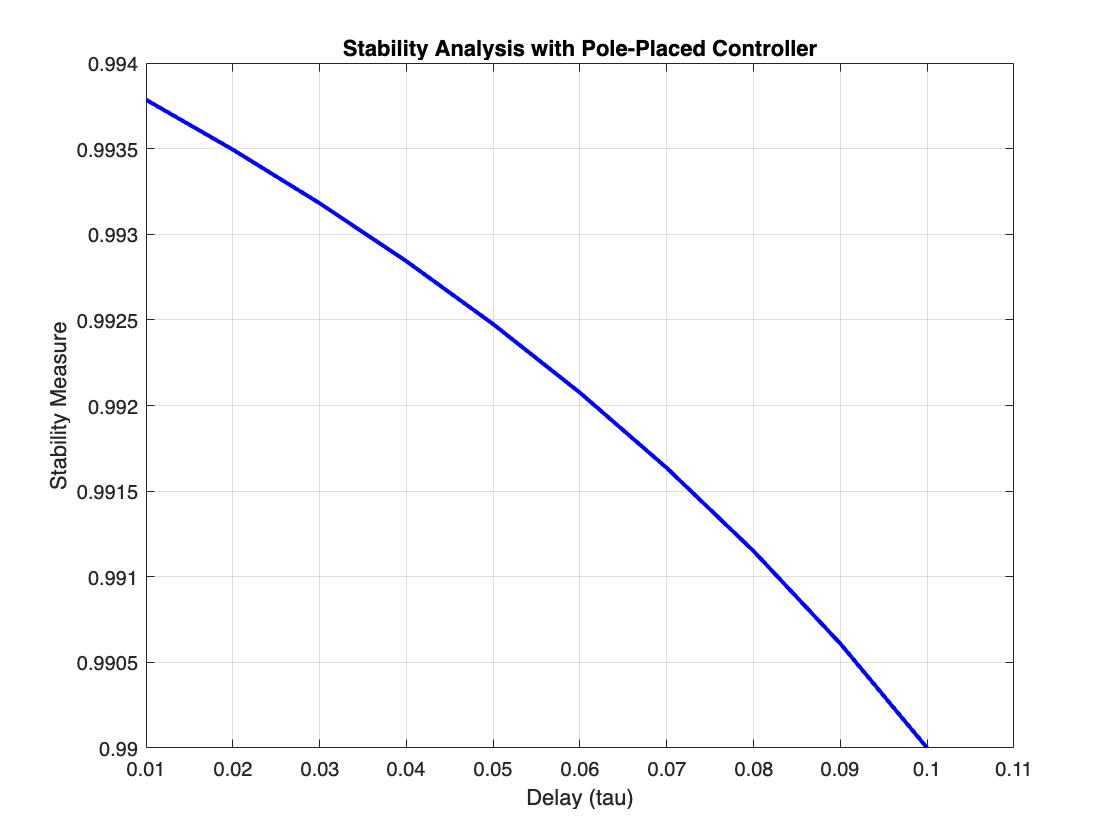

%Pole placement
% Define the system matrices A and B based on the given system
a = 5;
b = 3;
c = 1;
A = [a-b, 0.5-c; 0, 1];
B = [0; 1];

% Define the selected sampling interval(tau = h)
h = 0.1;
tau = h;

%when 0=<tau<h
        Fx = expm(A*h);
        Fu = (expm(A*h) - expm(A*(h-tau)))/A * B;
        G1 = (expm(A*(h-tau)) - eye(size(A)))/A * B;
        F = [Fx, Fu; zeros(1,2), zeros(1)];
        G = [G1; 1];


%when h<tau<=1.5h
        Fxh = expm(A*h);
        Fuh = (expm(A*h) - expm(A*(2*h-tau)))/A * B;
        Gh = (expm(A*(2*h-tau)) - eye(size(A)))/A * B;
        Feh = [Fxh, Fuh, Gh; zeros(size(Fxh)),[0;1],zeros(2,1)]; 
        Geh = [zeros(size(Fxh(:,1))); 1; 0];
        
% Desired closed-loop poles
desired_poles = [0.88, 0.99, 0.11, 0.22];

% Compute the feedback gain matrix K using pole placement
K = place(Feh, Geh, desired_poles);

% Compute the closed-loop system matrix with the pole-placed controller
Aclh = Feh - Geh*K;

% Check stability of the closed-loop system
eigvalsh = eig(Aclh);

% Calculate stability for different delay values
tau_values = 0.01:0.01:h;
stab_values = zeros(size(tau_values));

for i = 1:length(tau_values)
    tau = tau_values(i);
        Fxh = expm(A*h);
        Fuh = (expm(A*h) - expm(A*(2*h-tau)))/A * B;
        Gh = (expm(A*(2*h-tau)) - eye(size(A)))/A * B;
        Feh = [Fxh, Fuh, Gh; zeros(size(Fxh)),[0;1],zeros(2,1)]; 
        Geh = [zeros(size(Fxh(:,1))); 1; 0];
        

    % Compute the closed-loop system matrix with the pole-placed controller
    Acl = Feh - Geh*K;

    % Check stability of the closed-loop system
    eigvals = eig(Acl);
    max_eigval = max(abs(eigvals));
    stab_values(i) = max_eigval;
end

% Plot stability measure against delay (tau)
plot(tau_values, stab_values, 'b-', 'LineWidth', 2);
xlabel('Delay (tau)');
ylabel('Stability Measure');
title('Stability Analysis with Pole-Placed Controller');
grid on;